# Práctica 4. Mínimos cuadrados

## Ajuste de datos

1. Cargar datos del archivo de datos `datos.csv`

filename = 'datos.csv';
A = csvread(filename);
X = A(:,1);
Y = A(:,2); 

2. Escribir la matriz $\mathbf A$ el problema para un polinomio de grado 3;

[n,m] = size(A);
C1 = ones(n,1);

for i = 1:n
    X2(i) = X(i)^2;
    X3(i) = X(i)^3;
end

A = [C1, X, X2', X3']

A =     1.0000    0.1000    0.0100    0.0010
    1.0000    0.2000    0.0400    0.0080
    1.0000    0.3000    0.0900    0.0270
    1.0000    0.4000    0.1600    0.0640
    1.0000    0.5000    0.2500    0.1250
    1.0000    0.6000    0.3600    0.2160
    1.0000    0.7000    0.4900    0.3430
    1.0000    0.8000    0.6400    0.5120
    1.0000    0.9000    0.8100    0.7290
    1.0000    1.0000    1.0000    1.0000


3. Resolver la ecuación normal para obtener los coeficientes del polinomio 

Api = (A' * A)\A';
xsol = Api * Y

xsol =    -0.8277
    4.8679
   -4.7913
    1.5533


4. Representar el resultado aproximado comparándolo con los datos

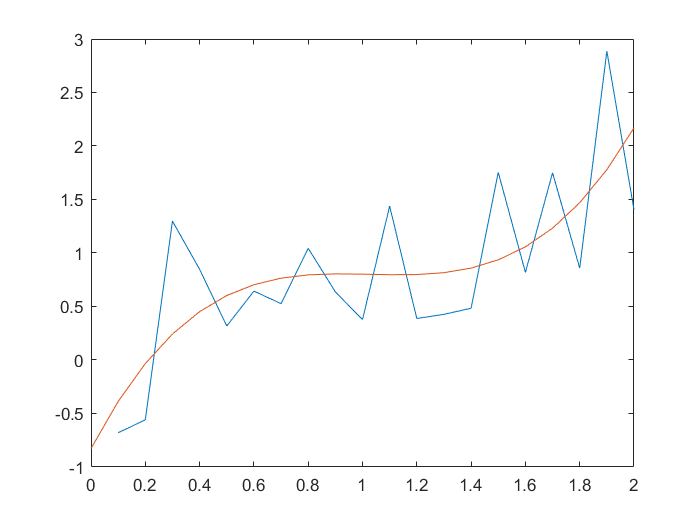

plot(X,Y)
hold on

for i = 1:4
    p(i) = xsol(4-i+1);
end

plot([0:0.1:2], polyval(p,[0:0.1:2]))

## Corrección de ruido en señales

1. Generar una señal dada por


$$x_k = sin(200 + k/75)-k/500, \qquad k=1, \cdots, 1000$$


for k = 1:1000
    %x = @(k) sin(200 + k/75) - k/500;
    x_(k) = sin(200 + k/75) - k/500;
end

2. Añadir ruido a la señal anterior, mediante la expresión 


$$y_k = x_k+\sigma*\eta_k, \qquad k=1, \cdots, 1000$$


donde $\eta_k$ son realizaciones independientes de una variable $N(0,1)$

**Observación.** La función `randn` de MATLAB genera realizaciones de un distribución $N
(0,1)$.

sigma = 0.05;

for k = 1:1000
    %y = @(k) x(k) + sigma * randn;
    y_(k) = x_(k) + sigma * randn;
end

3. Representar la señal sin ruido, y la señal ruidosa 

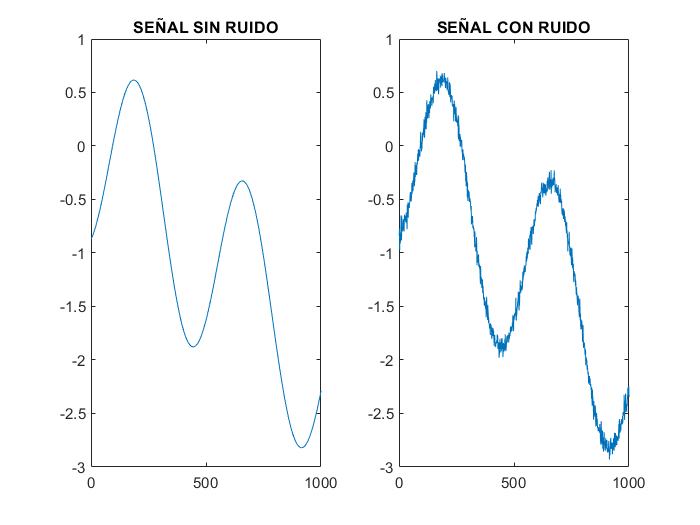

subplot(1,2,1)
plot(x_)
title('SEÑAL SIN RUIDO')

subplot(1,2,2)
plot(y_)
title('SEÑAL CON RUIDO')

4. Escribir, en el apéndice A1 una función que, dados $\lambda$ y un vector corriga la imagen. Debe responder a la sintaxis

    x = `correccion_ruido_1D(y, lambda)`

5. Probar la función anterior para 


$$\lambda=10^{i}, \qquad i = -1, 0, 1, \cdots, 4.$$
 

Representar la corección comparada contra el dato original con y sin ruido.

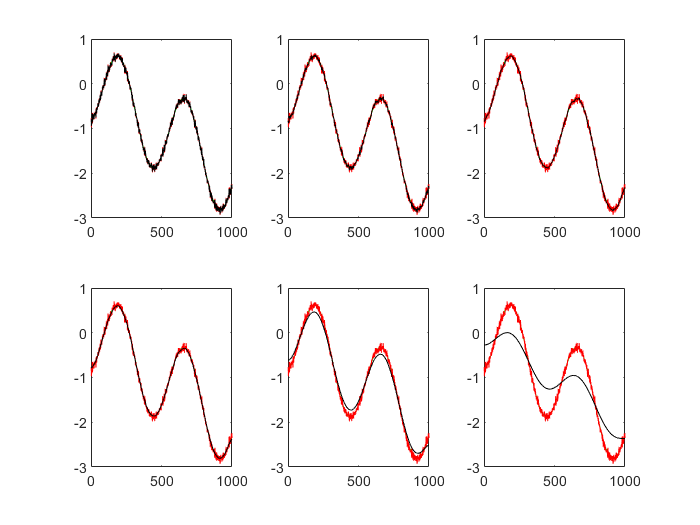

count = 1;
for i = -1:4
    lambda = 10 ^ i;
    x = correccion_ruido_1D(y_, lambda);
    
    subplot(2,3,count)
    
    plot(x_, 'g')
    hold on
    plot(y_, 'r')
    hold on
    plot(x, 'k')
    
    count = count + 1;
    
end

## Apéndice A. Funciones

A1. Función de corrección de ruido para vectores

function x = correccion_ruido_1D(y, lambda)
 
 D = zeros(length(y) - 1, length(y));
 
 for i = 1:(length(y) - 1)
     D(i,i) = 1;
     D(i, i+1) = -1;
 end
 
 x = y/(eye(length(y)) + lambda * D' * D);
 
end 